# Youla parameterization - Control of stable discrete processes: Advanced topic

This live script needs the control toolbox. 

The script goes through the main principles of control of stable discrete processes using Youla parameterization and shows its application through some examples.  

### Similar files and the toolbox

**discrete_models_and_discrete_PID_controller_design.mlx**

**Youla_continuous_controller_design_toolbox.mlx**

See website below for more control concepts.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
% There is a bug in 2024a: Try doc ("Control101 Toolbox")  or doc control101_toolbox.%
% help control101  % this line only works if the toolbox is installed

File written by László Keviczky and Ruth Bars, Budapest University of Technology and Economics  

                                  

**Reference****: Control Engineering **and** Control Engineering: MATLAB Exercises, by L. Keviczky, R. Bars, J. Hetthéssy, Cs. Bányász, Springer, 2019**

The related website has been developed and and some file editting made by J.A. Rossiter, University of Sheffield                             

                           

## Table of contents

- Mathematical background

- Controller design 

- Examples

                Example 1. Youla parameterised control of a first order system with dead time 

                Example 2. Youla parameterised control of a third order system

                Example 3. Youla parameterised control of a non-minimum phase process

## 1.Mathematical background

This script assumes the block diagram in Figure 1 with the system given by its transfer function* G(s)* and the compensator given by transfer function *M(s),  r* is the reference signal, *u* is the control signal and *y* is the output signal, * yni* and *yno* are the input and output disturbances, respectively and *yz* is the measurement noise. 

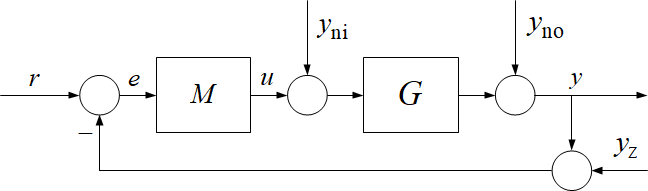

**Figure 1**: *Block diagram showing various disturbance inputs*

### 1.1 Sampled data systems

For computer control the output of the process *G* is sampled with a well chosen sampling time and this signal is forwarded to the process control computer via an analogue/digital A/D converter. The computer realises a reference signal in each sampling period and compares it with the output signal. This error signal* e* is the input to the control algorithm which calculates the control signal *u*. This signal is forwarded to the input of the process via a digital/analogue D/A converter. As the process is continuous, it requires a continuous control signal, which is obtained by holding the actual signal until the next sampling point, generally by a  zero order holding (ZOH) element, which keeps the actual control value constant during the sampling period. 

The block diagram of the sampled control system (without the disturbances) is shown in Figure 2 below. The part of the system in the dotted box is described by the *G(z)* pulse transfer function. The pulse transfer *M(z)* of the discrete controller has to be designed to fulfil the quality specifications set for the control system. 

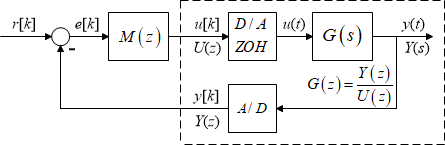

**Figure 2**: *Block diagram of the sampled data control system*

With an appropriately designed compensator (controller) the closed loop control system should ensure reference signal tracking and disturbance rejection and also attenuation of the effect of the measurement noise. Some earlier files have looked at different design approaches, for example:

- **discrete_models_and_discrete_PID_controller_design.mlx - **Discrete PID controller design with a pole cancellation technique 

- **Youla_continuous_controller_design.mlx - **Youla parameterized controller design for continuous case

It is noted that in  the discrete case the design is similar in principle to one performed in the continouous time case, but with minor adaptions to take account of using the pulse transfer functions.  The next section extends the continous Youla approach to the the discrete case and later on the file gives detailed examples and design steps.

### 1.2 The YOULA parameter and the control structure

The relationship between the control signal *u* and the reference signal *r* supposing no disturbances is given by the following relationship with the pulse transfer functions: 


$$\frac{U\left(z\right)}{R\left(z\right)}=\frac{M\left(z\right)}{1+G\left(z\right)M\left(z\right)}=Q\left(z\right)$$
      

The pulse transfer function *Q* is called the YOULA parameter. The resulting transfer function between the output signal y and the reference signal *r*  is  *T(z)=Q(z)G(z). * If *G* is stable, any stable *Q* ensures a stable closed loop control circuit. 

The series *M*(z) controller can be expressed with the YOULA parameter as:

$M\left(z\right)=\frac{Q\left(z\right)}{1-Q\left(z\right)G\left(z\right)}$.

With an appropriately designed compensator (controller) the closed loop control system should ensure reference signal tracking and disturbance rejection and also attenuation of the effect of the measurement noise. This livescript shows simple design techniques for the compensator *M(z). *As it will be seen the compensator can be designed in open loop ensuring good reference signal tracking and disturbance rejection is realised with IMC (Internal Model Control).

The block diagram of the control system with the Q parameter can be given as in Figure 3.

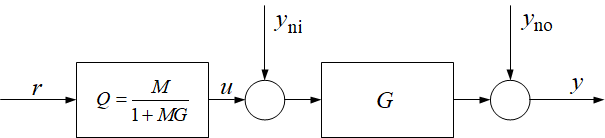

**Figure 3**: *Block diagram representation with a Youla parameter*

According to this structure the* Q* controller can be designed in open loop. The best controller choice would be $Q=G^{-1}$ because, if the Youla parameter is the inverse of the pulse transfer function of the process, then the resulting pulse transfer function of the closed loop would be unity. It should be mentioned that generally this transfer function is not realisable.

This open loop structure ensures reference signal tracking but does not reject the effect of the disturbances. To ensure disturbance rejection the control system is enhanced with internal model control as shown in Figure 4 below. Here only the output disturbance is indicated.

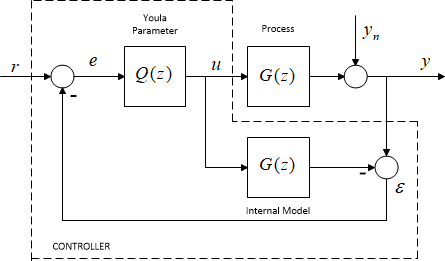

**Figure 4**: *Alternative block diagram of the sampled data control system with Internal Model Control*

This control structure can be redrawn as shown in Figure 5. below.

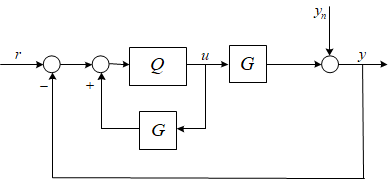

**Figure 5**: *Alternative* b*lock diagram representation of the sampled data control system*

If there is no disturbance and the internal model is exactly the same as the process, then the value of the feedback signal $\varepsilon$ is zero, and the reference signal tracking is determined by the forward path of the open loop. The feedback will ensure disturbance rejection and eliminates the effect of plant-model mismatch as well. 

If there is no model mismatch, then:


$$u=Q\left(r-y_n \right)$$



$$y=G\;u+y_n =G\;Q\;r-G\;Qy_n +y_n =T\;r+\left(1-T\right)y_n$$


**Remark: **The resulting closed-loop transfer function $T=Q\;G$ is linear in the parameter *Q*, while it is nonlinearly related to the series controller *M (e.g. *typically $T=\frac{G\;M}{1+G\;M}$). Therefore the design of parameter *Q* may be simpler than the design of the series controller *M*. 

The sensitivity function is given as:


$$S\left(z\right)=\frac{1}{1+M\;G}=1-Q\;G$$


The sensitivity function shows how the output disturbance affects the output signal, or similarly how the error signal is affected by the reference signal. If the frequency amplitude of the sensitivity function shows amplification in a given frequency range then the effect of the disturbance in this frequency range will be significant. This effect should be decreased.

The relationship between any input signal (i.e. *r, yni, yno, yz*) and any output signal (i.e. *y, u, e*) can also be given in terms of the *Q* parameter.

## 2. Controller design

### 2.1 Block diagram representations

As it was already mentioned the best controller choice would be $Q=G^{-1}$. If the Youla parameter is the inverse of the transfer function of the process, then the resulting pulse transfer function between the output and the reference signal would be unity. It should be mentioned that generally this transfer function is not realisable, as the transfer function of the process cannot usually be inverted and even if it could, the resulting compensator may not be robust and/or may result in over active inputs.

The pulse transfer function *G* of the process has to be separated to the cancellable $G_+ \left(z\right)$ and the non-cancellable $G_- \left(z\right)$ components. The discrete dead time is denoted by *d*. The discrete dead time cannot be cancelled.


$$G=G_+ G_- z^{-d}$$


- In case of lag elements there is always a  $z^{-1\;}$ term, so the discrete  *d*  dead time is calculated as the ratio of the $T_d$ physical dead time and the $T_s$ sampling time plus 1. Preferably choose the sampling time so that ratio $T_d /T_s$ is an integer. 

- The static gain of $G_- \left(z\right)$ should be 1 to ensure accurate reference signal tracking in steady state. Thus $G_- \left(z=1\right)=1\ldotp$

- The dead time cannot be cancelled. The zero of the pulse transfer function of the process which is outside of the unit circle also can not be cancelled, as this would result in an unstable pole in the controller. Also it is not expedient to cancel zeros which are on the left side of the unit circle, as this would introduce a pole in the controller causing intersampling oscillations in the control system.  

The block diagram of the discrete control system is shown in the Figure 6 below.

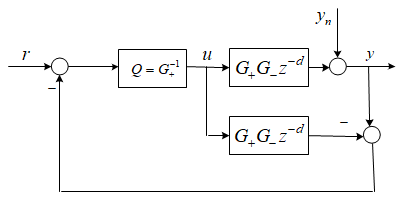

**Figure 6**:* Representation of the sampled data control system in terms of cancellable and non-cancellable components*

The Youla parameter performs the inverse of the invertible part of the transfer function of the model of the process: $Q=G_+^{-1}$

The dynamics of reference signal tracking and disturbance rejection is the same. Introducing a reference signal filter $R_r$ and a disturbance filter $R_n$ the dynamics of reference signal tracking and disturbance rejection will be different. The gain of the filters should be 1.

$R_r \left(z=1\right)=1$  and  $R_n \left(z=1\right)=1$.

The control structure extended with the filters is shown in Figure 7 below.

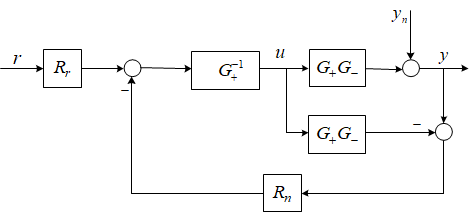

**Figure 7**: *Expanded control structure with filters*

This block diagram can be redrawn according to Figure 8.

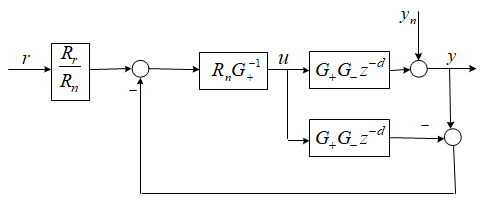

**Figure 8**: *Rearranged control structure with filters*

- The expression of the Youla parameter is now $Q=R_n G_+^{-1}$.

- Reference signal tracking is given by relationship ${y=R}_r G_- z^{-d} r$  and disturbance rejection by relationship $y=\left(1-R_n G_- z^{-d} \right)y_n$.

- Restructuring the figure the conventional feedback system is obtained as shown in Figure 9 below, where the series controller can be given as:

                    
$$M=\frac{R_n G_+^{-1} }{1-R_n G_- z^{\ldotp d} }=\frac{Q}{1-\textrm{QG}}$$


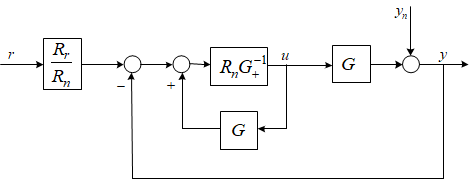

**Figure 9**: *Block* *diagram representation used for supporting control design*

With the filters the relationships between the signals are expressed as:


$$\left\lbrack \begin{array}{c}
u\\
e\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{R_r }{R_n }Q & -Q\\
\frac{R_r }{R_n }\left(1-\textrm{QG}\right) & -\left(1-\textrm{QG}\right)\\
\frac{R_r }{R_n }\textrm{QG} & 1-\textrm{QG}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r\\
y_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{R_r }{R_n }Q & -Q\\
\frac{R_r }{R_n }S & -S\\
\frac{R_r }{R_n }T & S
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r\\
y_n 
\end{array}\right\rbrack$$


### 2.2 The effect of the filters is threefold 

With different reference and disturbance filters the dynamics of reference signal tracking and the dynamics of disturbance rejection will be different. The behaviour of the filters should be faster than the behaviour of the process itself. The reference signal filter affects the maximum value of the control signal. The order of the filters should ensure the realisability of the Youla parameter *Q*. With the filters the robustness of the control system can also be influenced (this latter topic is not analysed here). Nevertheless a usable result by L. Keviczky and Cs, Bányász (see in Two-Degree-of-Freedom Control Systems, The Youla parameterisation Approach, Elsevier, 2015) is, that if the process is modelled by a lag element with dead time, and there is a mismatch between the dead time $T_d$ of the real process and the dead time ${\hat{T} }_d \;$of its model, then a robustness condition is obtained as:

$\left|1-\frac{{\hat{T} }_d }{T_d }\right|<\frac{T_n }{T_d }$  , where $T_n$ is the time constant of the disturbance filter given by a first order lag element.

### 2.3 Summarising the controller design: 

The transfer function of the process is separated into the invertible and non-invertible parts. To do this the user has to analyse the pulse transfer function: dead time is non-cancellable, zeros outside the unit circle are non-cancellable, zeros inside the unit circle located on the left half of the circle (or more precisely outside the "heart curve") are non-cancellable either. The reference and disturbance filters should be chosen as design objectives. Then the *Q* parameter is calculated ensuring good reference signal tracking in open loop.  The control system is realised in an IMC structure or the controller is transformed to the usual feedback form ensuring also good disturbance rejection. 

**Remark:** Dead beat control is a special case of the Youla parameterisation. It is the same as the Youla parameterisation algorithm without filters.

## **3. Examples**

For continuity and comparison, the same examples are given here as used in the continuous Youla controller design file (**Youla_continuous_controller_design_toolbox.mlx)**.

Some aspects are supported by a simulink simulation (***simulink_youla_control101.slx***) because this allows us to investigate inter-sample behaviour and confirm that the discrete design is not causing undesirable behaviours that are not apparent by only viewing the sample instants.

### **3.1 Example 1. Youla parameterised control of a first order system with dead time** 

The transfer function of the continuous process is


$$G\left(s\right)=\frac{2}{1+20s}e^{-10\;s}$$


The process is sampled with sampling time $T_s =2$. Design a discrete Youla parameterised controller for the process with the reference filter $R_r \left(s\right)=\frac{1}{1+5s}$ and disturbance filter $R_n \left(s\right)=\frac{1}{1+2s}$, which are also sampled with the same sampling time. Give the Q Youla parameter. Determine and plot the output signal for step reference signal supposing no output disturbance. Give also the control signal. Determine and plot the output signal for step output disturbance supposing no reference signal. Give also the control signal.

**Remark**: The non-cancellable part of the process is the dead time.

First define the model.

disp('BELOW IS SECTION 3.1: DISCRETE YOULA PARAMETERISED CONTROL OF A FIRST ORDER SYSTEM WITH DEAD TIME')
s=zpk('s');
Gp=2/(1+20*s);
disp('The continuous process')
Gm=exp(-10*s);
G=Gp*Gm
Ts=2; %d The sampling time
disp('The pulse transfer function of the process')
z=zpk('z',Ts);
Gd=c2d(Gp,Ts);
Gdd=Gd*z^-5
t=0:Ts:100;
t1=0:0.01:100;
ys=step(G,t1); % open-loop behaviour

Controller design steps: Define the filters and then *Q* and finally the closed-loop transfer functions.

disp('The filters')
Rr=1/(1+5*s);
Rrd=c2d(Rr,Ts)
Rn=1/(1+2*s);
Rnd=c2d(Rn,Ts)
% Rrd=1/z,  Rnd=1/z
disp('The YOULA parameter')
Q=minreal(Rnd/Gd,0.001)
disp('The pulse transfer function between the output and the reference signal')
T=minreal((Rrd/Rnd)*Q*Gdd,0.001)
disp('The pulse transfer function between the control signal and the reference signal')
U=minreal((Rrd/Rnd)*Q,0.001)

Closed-loop simulation: Plot and evaluate the resulting behaviour.

y=step(T,t); % response to changes in r
yn=step(1-Rnd*z^-1,t); % response to changes in output disturbance
plot(t,y,t,yn,t1,ys),grid
title('Output behaviour for different inputs')
legend('step reference','step output disturbance','open-loop','Location','Southeast')

u=step(U,t); % input response for target changes
stairs(t,u),grid
title('Control signal in case of step reference signal')

- It is seen that the control ensures a faster settling than that of the process itself. This is ensured by the over-excitation in the contol signal; the transient input is well above the steady-state. 

- It is seen that disturbance rejection is faster than reference signal tracking because of the choice of different filters.

- The control signal consists of the sampled and held values, while the output signals are continuous (visualised by commands stairs and plot).

#### 3.1.1 Tasks. 

The file user can use and edit the code above to investigate different design choices, for example, how does the control behaviour change with different filters.

#### 3.1.2 Use of simulink

The simulink file** simulink_youla_control101.slx** was built to simulate the performance of the control system. The effect of reference signal tracking and output disturbance rejection and also the effect of dead time mismatch can be analysed easily. A step reference signal is applied and shifted by 100 sec and an output disturbance step is added with 0.5 amplitude.

Illustrative code on how to use the simulink file is given below, including which simulation data needs defining. This assumes the data in section 3.1 has been created.

disp('Section 3.1.2')
% Simulation
deadtime=10;   % in seconds not samples
deadtimem=10;  % deadtime of the model. Change this value to create a mismatch
endtime=150;
tplot = 0.2;  % Sample rate for collecting continuous data from simulink - faster than sample rate

% Run simulation and collate outputs into convenient variables
Data= sim('simulink_youla_control101.slx');
y=Data.y.signals.values;
u=Data.u.signals.values;
t = Data.u.time;
ydiscrete=Data.ydiscrete.signals.values;
tdiscrete = Data.ydiscrete.time;

% Plotting
plot(t,y,'b',tdiscrete,ydiscrete,'ro'),grid
legend('Continuous values','Sampled values','Location','Southeast')
xlabel('Time (sec)')
title('Step response of a youla control system using simulink')
stairs(t,u),grid  % useful function to avoid MATLAB interpolating between different values
title('Control signal from simulink simulation')
xlabel('Time (sec)')

### **3.2 Example 2. Youla parameterised control of a third order system **

The transfer function of the process is:

$G\left(s\right)=\frac{1}{\left(1+2s\right)\left(1+5s\right)\left(1+10s\right)}$.

The process is sampled with sampling time $T_s =$1.

Design a Youla parameterised controller with filters which are also sampled with the same sampling time.

$R_r =\frac{1}{{\left(1+2s\right)}^3 }$; $R_n =\frac{1}{{\left(1+4s\right)}^3 }$.

Give the Youla parameter. Determine and plot the output signal for step reference signal supposing no output disturbance. Give also the control signal. Determine and plot the output signal for step output disturbance supposing no reference signal. Give also the control signal.

disp('BELOW IS SECTION 3.2: DISCRETE YOULA PARAMETERISED CONTROL OF A THIRD ORDER SYSTEM')
s=zpk('s');
disp('The process')
G=1/((1+2*s)*(1+5*s)*(1+10*s))
Ts=1; % The sampling time
disp('The pulse transfer function of the process')
z=zpk('z',Ts);
Gd=c2d(G,Ts)
% Step response of the process')
to=0:0.01:100;
yo = step(G,to);


The following code separates the system into the cancellable and non-cancellable parts, defines the filters and does the control law design.

%Separate Gd to invertible and non-invertible parts
Gdm=(1+3.068*z^-1)/4.068
Gdp=minreal(Gd/Gdm,0.0001)
disp('The filters')
Rn=1/(1+4*s)^3;
Rr=1/(1+2*s)^3;
Rrd=c2d(Rr,Ts)
Rnd=c2d(Rn,Ts)
% Alternative choices
% Rn=1/((1+4*s)*(1+2*s)),  Rr=1/((1+s)*(1+s)), Rrd=c2d(Rr,Ts), Rnd=c2d(Rn,Ts)  
% Rn=1/(1+s), Rr=1/(1+2*s),  Rrd=c2d(Rr,Ts),  Rnd=c2d(Rn,Ts)

% Youla design
disp('THE YOULA PARAMETER')
Q=minreal(Rnd/Gdp,0.0001)
T=minreal((Rrd/Rnd)*Q*Gd,0.0001);
U=minreal((Rrd/Rnd)*Q,0.0001);

% Closed-loop simulation and plotting
t=0:Ts:100;
y=step(T,t);
plot(t,y,to,yo),grid
legend('Closed-loop','Open-loop','Location','Southeast')
title('The output signal (with a step input)')
u=step(U,t);
stairs(t,u),grid
title('The closed-loop control signal')

It is seen that the settling of the control system is much faster than the settling of the open-loop process, but this speed up is achieved at the price of overexcitation in the control signal.

**Student tasks:** Check the performance with different filters (some alternatives are provided in the code above). You may also wish to investigate behaviour for input and output disturbances.

### **3.3 Example 3. Youla parameterised control of a non-minimum phase process**

The transfer function of the process is:


$$G\left(s\right)=\frac{1-s}{\left(1+s\right)\left(1+2s\right)}$$


Design a Youla parameterised controller with filters:

$R_r =\frac{1}{{\left(1+0\ldotp 8s\right)}^2 }$; $R_n =\frac{1}{\left(1+0\ldotp 2s\right)\left(1+0\ldotp 5s\right)}$.

The process is sampled with sampling time $T_s =0\ldotp 2$. The numerator of the model of the process cannot be cancelled, as it would introduce an unstable pole in the controller.

disp('BELOW IS SECTION 3.3: DISCRETE YOULA PARAMETERISED CONTROL OF A NON-MINIMUM PHASE PROCESS')
s=zpk('s');
disp('The process')
G=(1-s)/((1+s)*(1+2*s))
% Open-loop step response of the process
to=0:0.1:15;
yo = step(G,to);
Ts=0.2; % The sampling time
z=zpk('z',Ts);
Gd=c2d(G,Ts); % The pulse transfer function of the process


Control design aspects (uncomment variables to see them displayed in the right hand window)

%Separate Gd to invertible and non-invertible parts
Gdm=(1-1.224*z^-1)/(-0.224);
Gdp=minreal(Gd/Gdm,0.000001);
% The filters
Rn=1/((1+0.2*s)*(1+0.5*s))
Rr=1/(1+0.8*s)^2
Rrd=c2d(Rr,Ts);
Rnd=c2d(Rn,Ts);
% Youla design
Q=Rnd/Gdp;
Q1=minreal(Q,0.001);


Closed-loop transfer functions and simulation (only reponses to a change in target  are shown here).

T=(Rrd/Rnd)*Q1*Gd;
U=(Rrd/Rnd)*Q1;

t=0:Ts:15;
y=step(T,t);
plot(t,y,to,yo),grid
legend('Closed-loop','Open-loop','Location','Southeast')
title('The output signal')

u=step(U,t);
stairs(t,u),grid
title('The closed-loop control signal')

It is seen that the settling of the closed-loop system is much faster than the open-loop but obviously the non-minimum-phase characteristic has remained.

**Student tasks:** Check the performance with different filters and consider how these might be selected systematically. You may also wish to investigate behaviour for input and output disturbances.

### **3.4 Example 4. Youla parameterised control of a second order process with a large dead time**

The transfer function of the process is:


$$G\left(s\right)=\frac{1}{\left(1+5s\right)\left(1+10s\right)}e^{-30s}$$


The sampling time is $T_s =1$.

Design a Youla parameterised controller with filters $R_r =R_n =\frac{1}{{\left(1+s\right)}^2 }$; Then choose the input filter as $R_r =\frac{1}{\left(1+2s\right)\left(1+s\right)}$. Give the Youla parameter. Plot the output signal for step reference input and for step reference disturbance. Plot also the corresponding control signals. Analyse the behaviour of the system with different filters.  

disp('BELOW IS SECTION 3.4: DISCRETE YOULA PARAMETERISED CONTROL OF A THIRD ORDER PROCESS WITH BIG DEAD TIME')

BELOW IS SECTION 3.4: DISCRETE YOULA PARAMETERISED CONTROL OF A THIRD ORDER PROCESS WITH BIG DEAD TIME


s=zpk('s');
disp('The process')

The process


Gp=1/((1+5*s)*(1+10*s));
G1=Gp*exp(-30*s)

G1 =
 
                    0.02
  exp(-30*s) * ---------------
               (s+0.2) (s+0.1)
 
Continuous-time zero/pole/gain model.
Model Properties


% Step response of the process
to=0:0.1:150;
yo = step(G1,to);
Ts=1;  % The sampling time
% The pulse transfer function of the process')
z=zpk('z',Ts);
Gd=c2d(Gp,Ts);
Gdd=Gd*z^-30;


Control law specifications and design (uncomment variables to see them displayed in the right hand window)

Gdm=(1+0.9048*z^-1)/1.9048;
Gdp=minreal(Gd/Gdm,0.000001);
% The filters
% Rn=1/(1+s)^2  Rr=1/(1+s)^2 alternatives
disp('The filters')

The filters


Rn=1/(1+s)^2

Rn =
 
     1
  -------
  (s+1)^2
 
Continuous-time zero/pole/gain model.
Model Properties


Rr=1/(1+s)^2

Rr =
 
     1
  -------
  (s+1)^2
 
Continuous-time zero/pole/gain model.
Model Properties


Rrd=c2d(Rr,Ts);
Rnd=c2d(Rn,Ts);
%Youla design
Q=Rnd/Gdp;
Q1=minreal(Q,0.001);


Closed-loop transfer functions and simulation

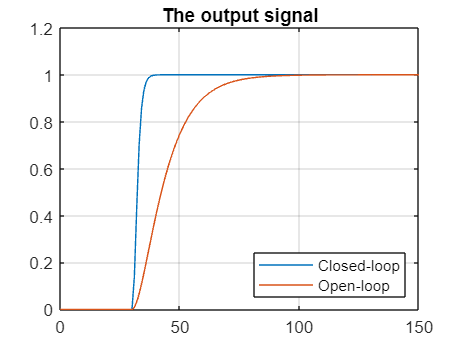

T=(Rrd/Rnd)*Q1*Gdd;
U=(Rrd/Rnd)*Q1;

t=0:Ts:150;
y=step(T,t);
plot(t,y,to,yo),grid
title('The output signal')
legend('Closed-loop','Open-loop','Location','Southeast')

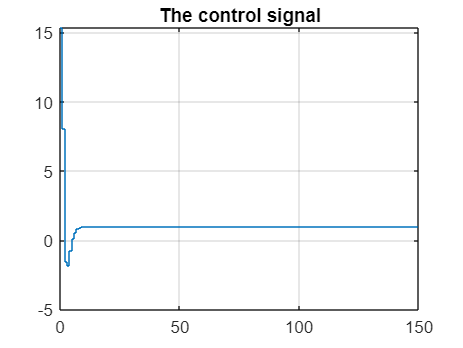


u=step(U,t);
stairs(t,u),grid
title('The control signal')

It is seen that the settling is much faster than the dynamics of the process on the price of overexcitation in the control signal.

**Tasks**: Check the performance with different filters. 

**Task 2:** Analyse the behaviour with the simulink program to investigate intersample behaviour. (Some helpful code is given next.)

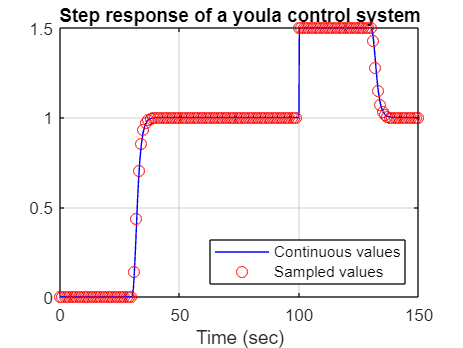

% Simulation
deadtime=30;  % in seconds not samples
deadtimem=30;
endtime=150;
tplot =0.2 ;  % Sample rate for collecting data from simulink (must be faster than sample rate)
Data= sim('simulink_youla_control101.slx');
y=Data.y.signals.values;
u=Data.u.signals.values;
t = Data.u.time;
ydiscrete=Data.ydiscrete.signals.values;
tdiscrete = Data.ydiscrete.time;

% Plotting
plot(t,y,'b',tdiscrete,ydiscrete,'ro'),grid
legend('Continuous values','Sampled values','Location','Southeast')
xlabel('Time (sec)')
title('Step response of a youla control system')

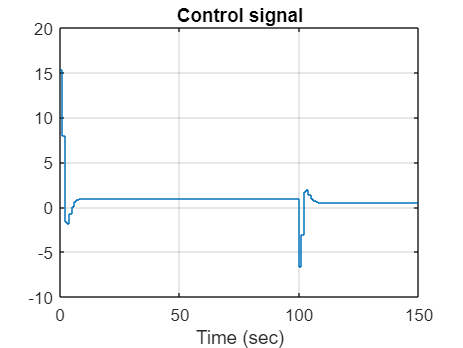

stairs(t,u),grid  % useful function to avoid MATLAB interpolating between different values
title('Control signal')
xlabel('Time (sec)')